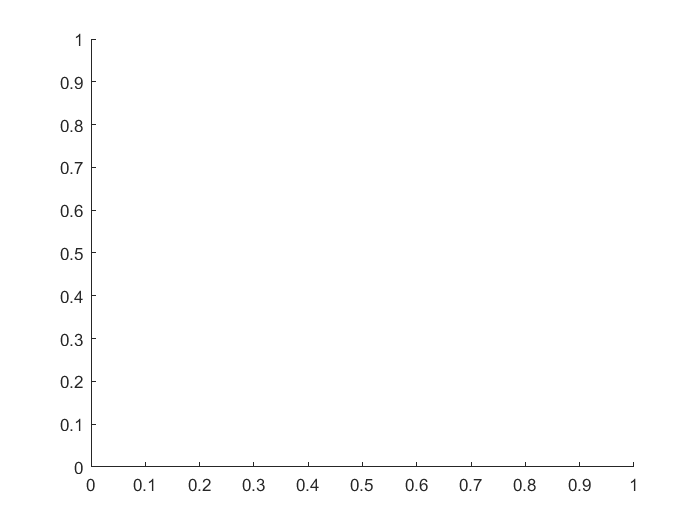

dist2plane = 85; draw = 0;
[Nref, target_cen, p2, p_xray, h_xray, pivot_point] = PIXLmodel(dist2plane);

O_sparse = [-4.97106199398101	-23.3166644021243	25.9323627986420];
    
unit_vec_sparse = ...
[-0.288747648637093	    0.306293242445162	0.907088333647269	19; ...
-0.158749579397549	    0.489889012839238	0.857209032932166	24; ...
-0.109768703619059	    0.203271681156385	0.972949872987117	27; ...
-0.0907968144078339	    0.0381900376058185	0.995136904913618	29; ...
-0.00567908914511474	0.521497048049676	0.853234186388448	30; ...
0.0207666893788740	    0.386062644452971	0.922238786416089	32; ...
0.0437189127391662	    0.236202180725793	0.970719932055217	34; ...
0.171328431220356	    0.404572093780863	0.898313970496586	38; ...
0.193597326951717	    0.255385818084361	0.947258232436400	40; ...
0.360415150717705	    0.0970278401199079	0.927731921071384	48; ...
-0.132920541223632	    0.353306930817220	0.926016383417341	153; ...
0.0622579867034057	    0.0721187237278580	0.995451070007714	165; ...
0.319234128656939	    0.411526809366900	0.853659918394289	170; ...
0.212495249872407	    0.0913461994675134	0.972883158773192	171; ...
0.341601505721431	    0.261113540324678	0.902844466310762	173];
    
Ipred = [];
for i = 1:length(hexa_pos)
        % Create rotation matrix
    R = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    %R = createRotationMatrix(yaw, pitch, roll);
    R = [R, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    % Rotation to align with base-frame
    best_angle_x = 18; % 18.27;
    best_angle_y = 0;  % -0.38;
    best_angle_z = 0;  % 0.2700;
    Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
    Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    %T_rot = [1, 0, 0, hexa_pos(1, j); 0, 1, 0, hexa_pos(2, j); 0, 0, 1, hexa_pos(3, j); 0, 0, 0, 1];
    %T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
    %T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray; 0, 0, 0, 1];
    
    % pivot_point_r = (T_base^-1*T_p2*Rc*T_p2^-1*[pivot_point, 1]')'; 
    %pivot_point_r = (Rc*T*[pivot_point, 1]')';
    % c2x_y = 23%*10^3;        %um
    % x2c_z = 22.997;          %um
    %T_pivot = [1, 0, 0, pivot_point_r(1); 0, 1, 0, pivot_point_r(2); 0, 0, 1, pivot_point_r(3); 0, 0, 0, 1];
    T_pivot = [1, 0, 0, 0; 0, 1, 0, c2x_y/1e3; 0, 0, 1, 190-desired_distance/1e3-x2c_z/1e3; 0, 0, 0, 1];
    
    %[0 c2x_y (pivot_point-desired_distance-x2c_z)]';
    %RT = R*T_rot*Rc*T_pivot^-1;
    
    RT = R*Rc*T_pivot;
        
    pos_rot = RT*[target_cen, 1]';
    pos_rot = pos_rot(1:3)';
    
    O_SLI = RT*[O_sparse, 1]';
    O_SLI = O_SLI(1:3)';

    uv = unit_vec_sparse;
    Ix = zeros(size(uv(:, :)));
    clf
    figure(5)
    hold on
% With translaltion
    for i = 1:size(uv, 1)    
        % Rotate unit vectors (uv) first to the base-frame, then the
        % specified angles
        uv_ = R*Rc*[uv(i, 1 :3), 1]';
        uv_ = uv_(1:3)';
        % Find out where the rotated unit vectors intersect with the plane
        [Ix_, ~] = line_plane_intersection(uv_, O_SLI, [0, 0, 1], pos_rot);
        N = (pos_rot - O_SLI)./norm(pos_rot - O_SLI);
        [Ix_, ~] = line_plane_intersection(N, Ix_, [0, 0, 1], target_cen); %Nref.*dist2plane + O);
        Ix(i, :) = [Ix_, uv(i, 4)];
        % If specified with 'draw', the lines can be drawn.
        drawLine(Ix(i, 1:3), O_SLI, draw, 'blue');
        Ipred = [Ipred; Ix(i, :)];
    end
end

    
     
    % for j = 1:size(rot_opt)
%     
%     for i = j
%         I_sparse = rotateSLI(Nref, uv_xray, O_sparse, unit_vec_sparse, pivot_point, dist2plane, pos3, p_xray, rot(i, :), [0.5, 0.5, 0.5], 0);
%         I_dense = rotateSLI(Nref, uv_xray, O_dense, unit_vec_dense, pivot_point, dist2plane, pos3, p_xray, rot(i, :), [0.5, 0.5, 0.5], 0);
%         I = [I; [[I_sparse, j*ones(size(I_sparse, 1), 1)]; [I_dense, j*ones(size(I_dense, 1), 1)]]];
%     end
%     
%     for i = 1:
%             I_sparse = reprojectSLI(p_xray, unit_vec_sparse, p2, h_xray, pivot_point, target_cen, rot_apriori(i, :), c(i, :), view(i));
%             I_apriori = [I_apriori; [[I_sparse, i*ones(size(I_sparse, 1), 1)]]];
%     end